# Diskrete Signaler Aflevering 2

## Filter fra poler og zeroes

### Example c12.2 fra Lathi

**Hej**

![test](/hej.png)

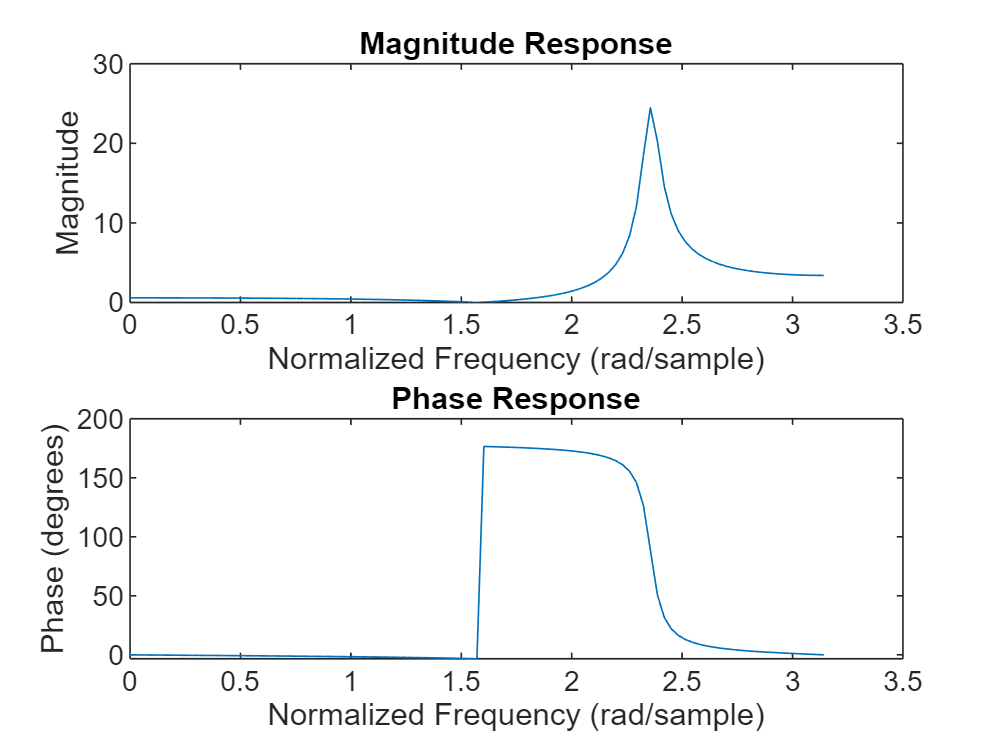

clf;
gamma = 0.96;
num = [-gamma, 0, -gamma]; %zeroes
den = [-1, -sqrt(2)*gamma, -gamma^2]; %poler
W = -pi:pi/100:pi;
H = freqz(num, den, W);
mag = abs(H);
phase = 180/pi * unwrap(angle(H));

% Sampling frequency (Hz)
fs = 1000; % Example value, change this to your actual sampling frequency
F = W * fs / (2 * pi); % Convert from rad/sample to Hz

% Normalize the frequency axis
F_normalized = pi*F / (fs / 2); % Normalized frequency (0 to 1)

% Only consider positive frequencies
positive_freq_indices = F >= 0;
F_positive = F_normalized(positive_freq_indices);
mag_positive = mag(positive_freq_indices);
phase_positive = phase(positive_freq_indices);

figure;
subplot(2,1,1)
plot(F_positive, mag_positive)
xlabel('Normalized Frequency (rad/sample)')
ylabel('Magnitude')
title('Magnitude Response')

subplot(2,1,2)
plot(F_positive, phase_positive)
xlabel('Normalized Frequency (rad/sample)')
ylabel('Phase (degrees)')
title('Phase Response')

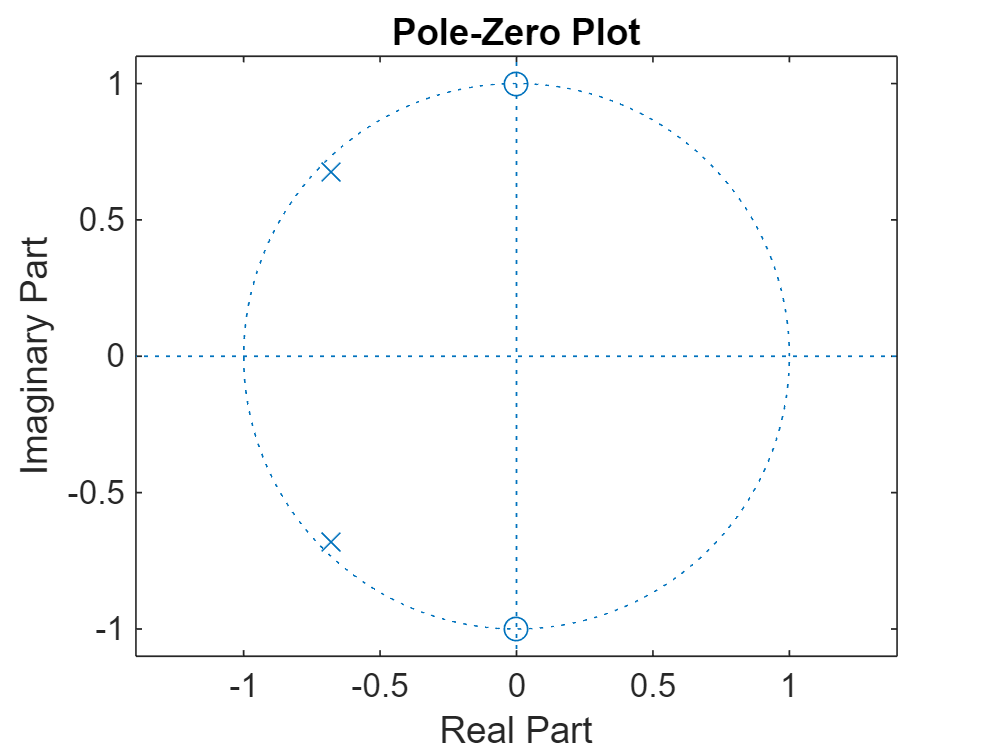


% Separate figure for pole-zero plot
figure;
zplane(num, den)
title('Pole-Zero Plot')

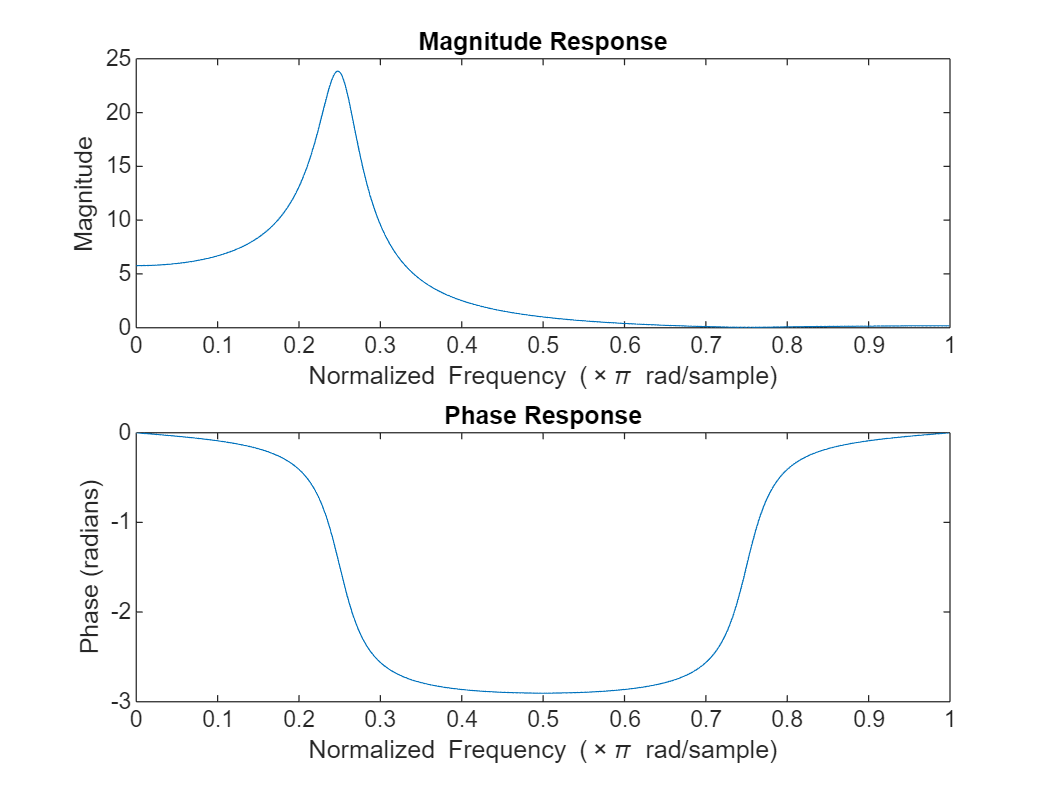

% Define poles and zeros
poles = [0.65 + 0.65i; 0.65 - 0.65i]; % Example poles (column vector)
zeros = [-0.65 + 0.65i; -0.65 - 0.65i];   % Example zeros (column vector)

% Create transfer function
[num, den] = zp2tf(zeros, poles, 1);

% Frequency response
[H, w] = freqz(num, den, 'half', 1024);

% Plot magnitude and phase response
figure;
subplot(2,1,1);
plot(w/pi, abs(H));
title('Magnitude Response');
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude');

subplot(2,1,2);
plot(w/pi, angle(H));
title('Phase Response');
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Phase (radians)');

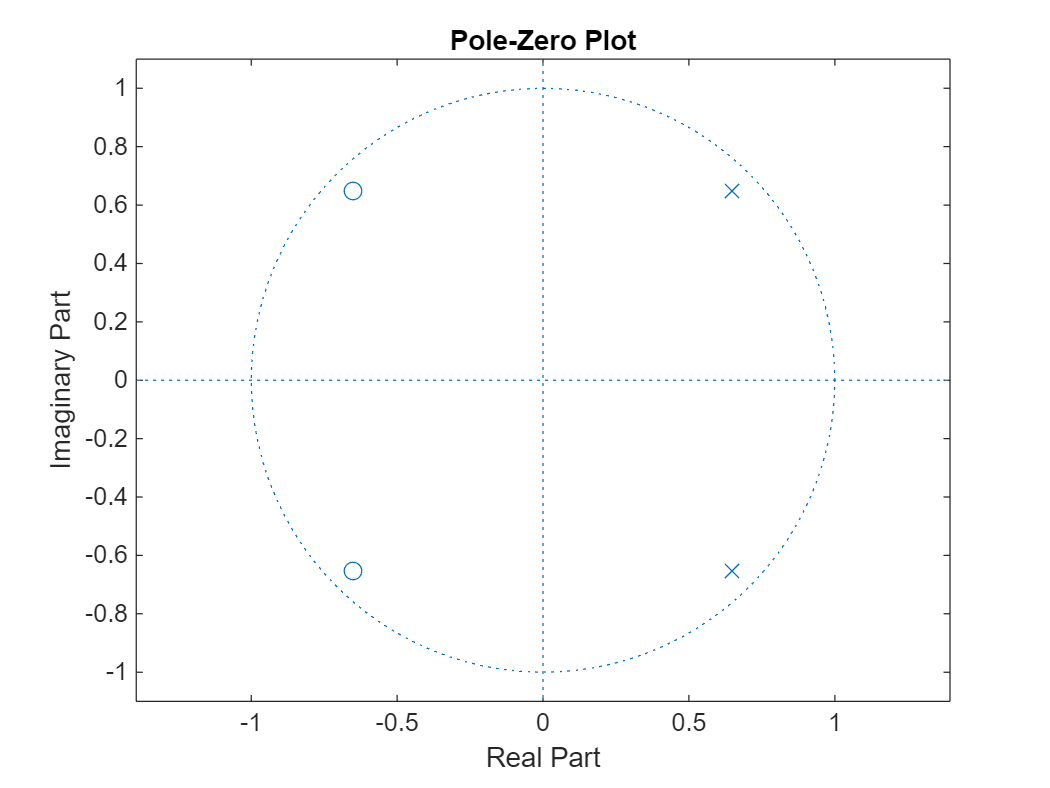


% Plot pole-zero plot
figure;
zplane(num, den);
title('Pole-Zero Plot');

## Equalizer med 12 Bånd

#### Taget fra uge 9

Først en funktion som tegner det ønskede filter

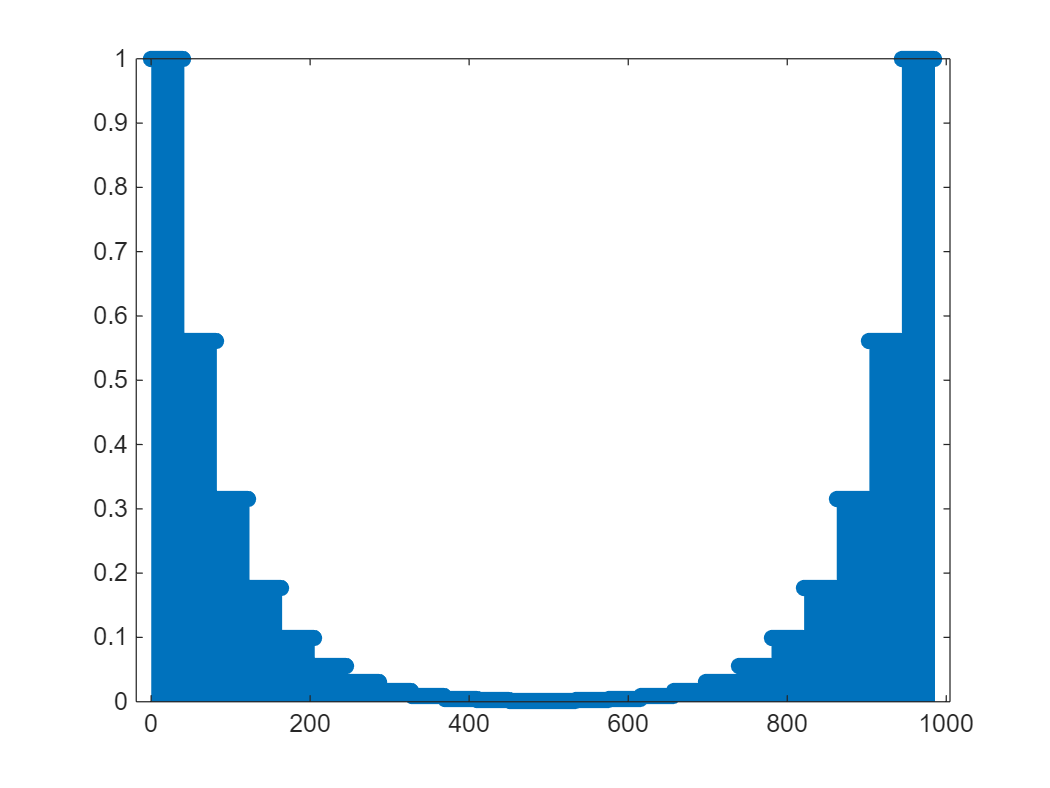

clear;

function [H, h] = Equalizer(G, N)
    G = db2mag(G);

    H = []; %Freq response

    %Positiv side af H
    for k = 1:length(G)
        H = [H, G(k) * ones(1, floor(N / (2 * length(G))))];
    end

    H = [H, G(length(G)), fliplr(H)];  %Mirror

    h = ifftshift(ifft(H, 'symmetric'));  %Convert to timedomaine

end

gains = [0, -5, -10, -15, -20, -25, -30, -35, -40, -45, -50, -55]; %db gains

[H, h] = Equalizer(gains, 1000); % Har leget med npgle forskellige ordner af filter n=1000 giver et meget fint resultat men også en meget høj orden
% Hvis orden bliver for lav begynder signalet at oscillere meget mod de
% mere dæmpede dele af signalet

%PLOT
stem(H)

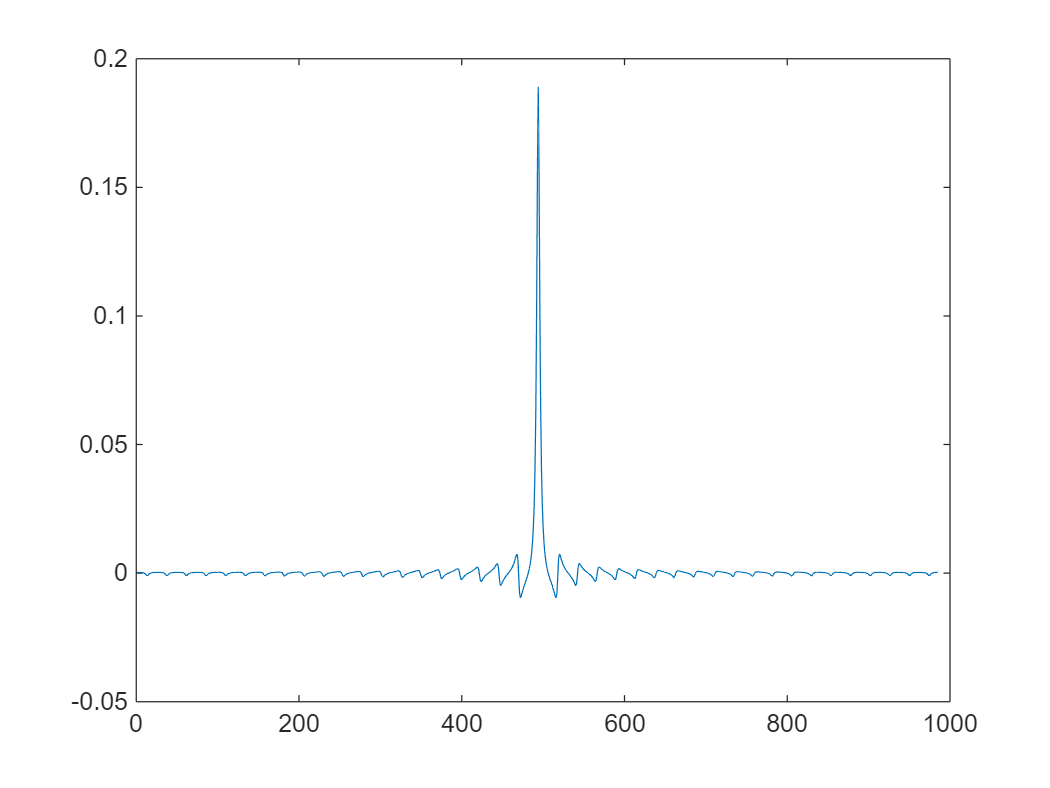


plot(h) %plotter impulsresponset af det givne filter da dette er symetrisk betyder det at filtret er linært

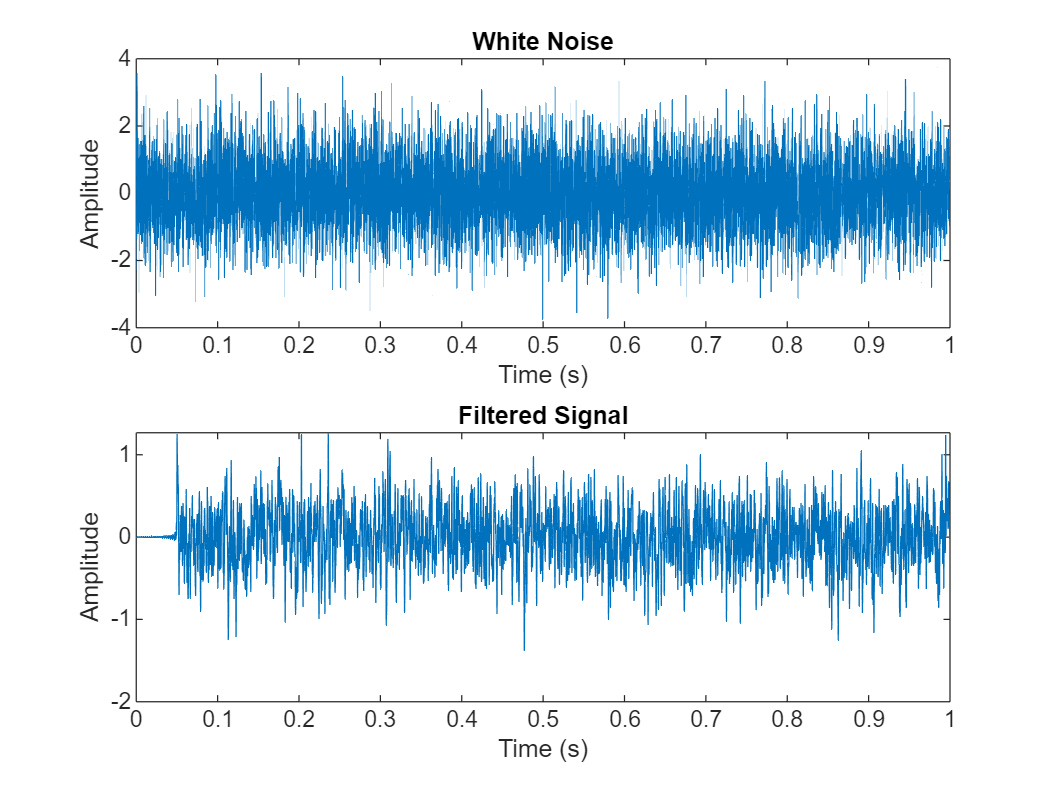

%If the impulse response is symmetric, it indicates that the filter is linear-phase,
% meaning it preserves the phase relationships of the input signal.


%laver White noise
clf;
% Define the impulse response of the filter
impulseResponse = h;

% Generate white noise
Fs = 10000; 
duration = 1; % (seconds)
whiteNoise = randn(Fs * duration, 1);

% Filter the white noise using the impulse response
filteredSignal = filter(impulseResponse, 1, whiteNoise);

% Plot the original and filtered signals
t = (0:length(whiteNoise)-1) / Fs;
figure;
subplot(2,1,1);
plot(t, whiteNoise);
title('White Noise');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, filteredSignal);
title('Filtered Signal');
xlabel('Time (s)');
ylabel('Amplitude');

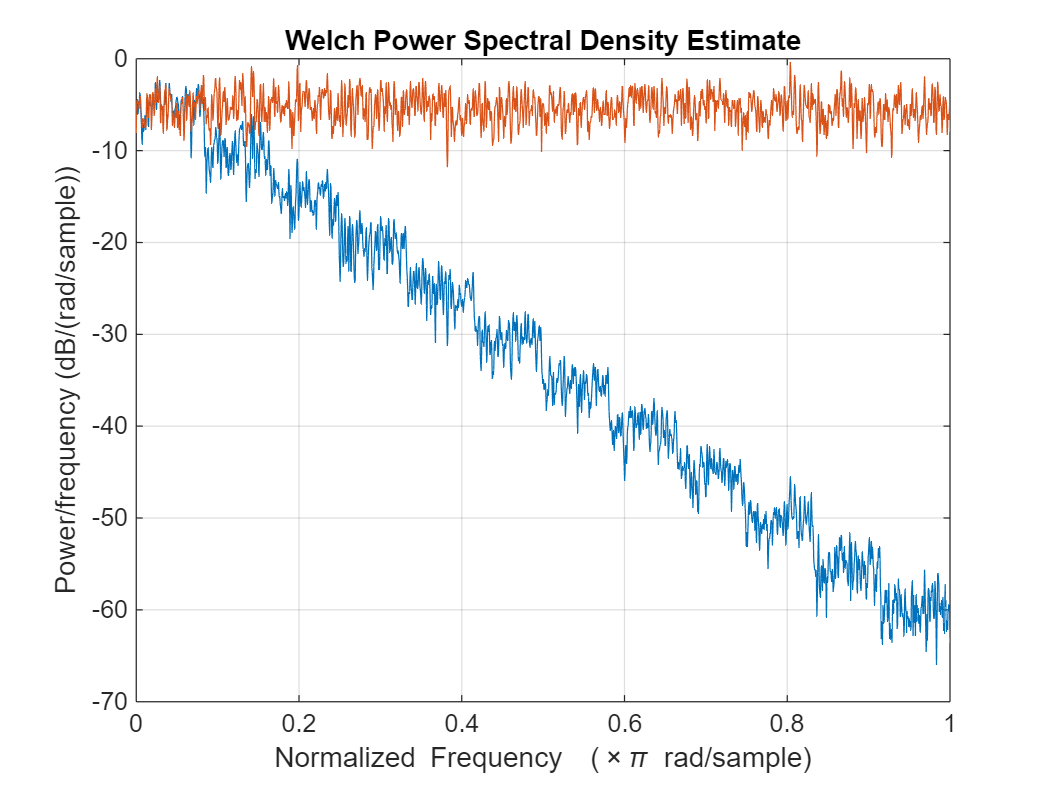


clf;
pwelch(filteredSignal, [],[],[],'onesided') %Måske burde den køres 'twosided, men er ikke sikker
hold on;
pwelch(whiteNoise,[],[],[], 'onesided') %Måske burde den køres 'twosided, men er ikke sikker
hold off;

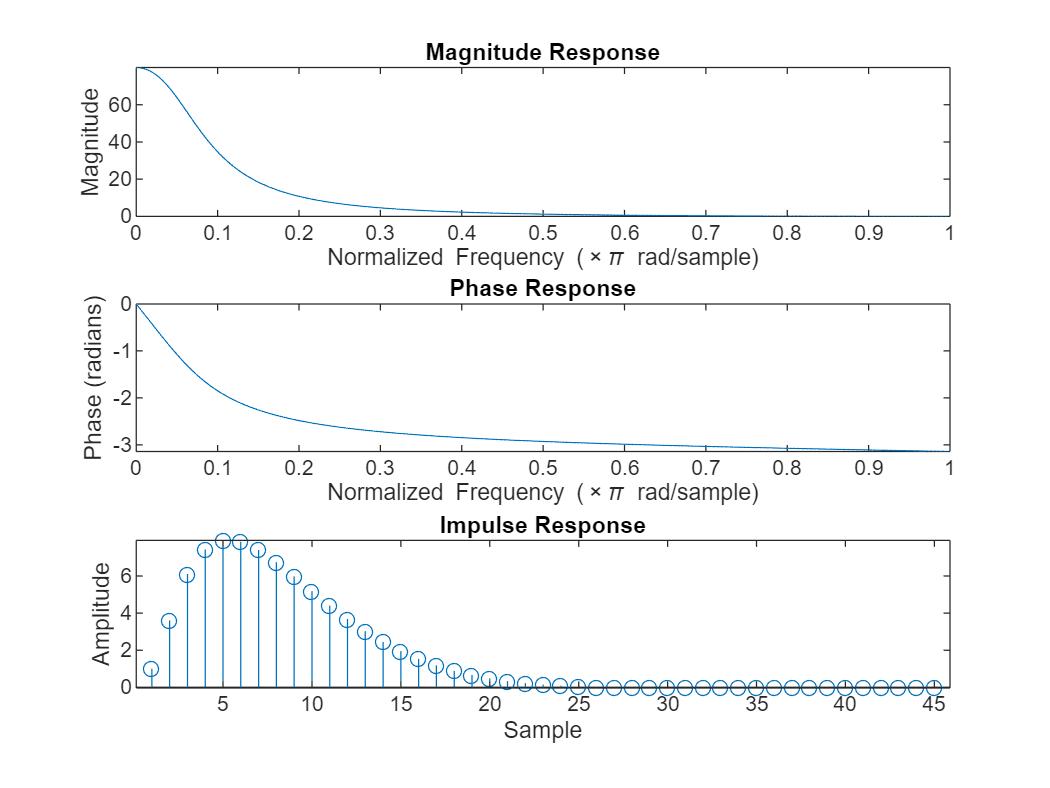

% Define filter type
filter_type = 'lowpass'; % Change to 'highpass', 'bandpass', or 'bandstop'

switch filter_type
    case 'lowpass'
        poles = [0.8 + 0.1i; 0.8 - 0.1i]; % Example poles for lowpass
        zeros = [-1; -1];                 % Example zeros for lowpass
    case 'highpass'
        poles = [-0.8 + 0.1i; -0.8 - 0.1i]; % Example poles for highpass
        zeros = [0; 0];                     % Example zeros for highpass
    case 'bandpass'
        poles = [0.8*exp(1i*pi/4); 0.8*exp(-1i*pi/4)]; % Example poles for bandpass
        zeros = [0; 0; -1; -1];                       % Example zeros for bandpass
    case 'bandstop'
        poles = [0.8*exp(1i*pi/4); 0.8*exp(-1i*pi/4)]; % Example poles for bandstop
        zeros = [exp(1i*pi/4); exp(-1i*pi/4)];         % Example zeros for bandstop
end

% Create transfer function
[num, den] = zp2tf(zeros, poles, 1);

% Frequency response
[H, w] = freqz(num, den, 'half', 1024);

% Plot magnitude and phase response
figure;
subplot(3,1,1);
plot(w/pi, abs(H));
title('Magnitude Response');
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude');

subplot(3,1,2);
plot(w/pi, angle(H));
title('Phase Response');
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Phase (radians)');

% Impulse response
impulse_response = impz(num, den);
subplot(3,1,3);
stem(impulse_response);
title('Impulse Response');
xlabel('Sample');
ylabel('Amplitude');

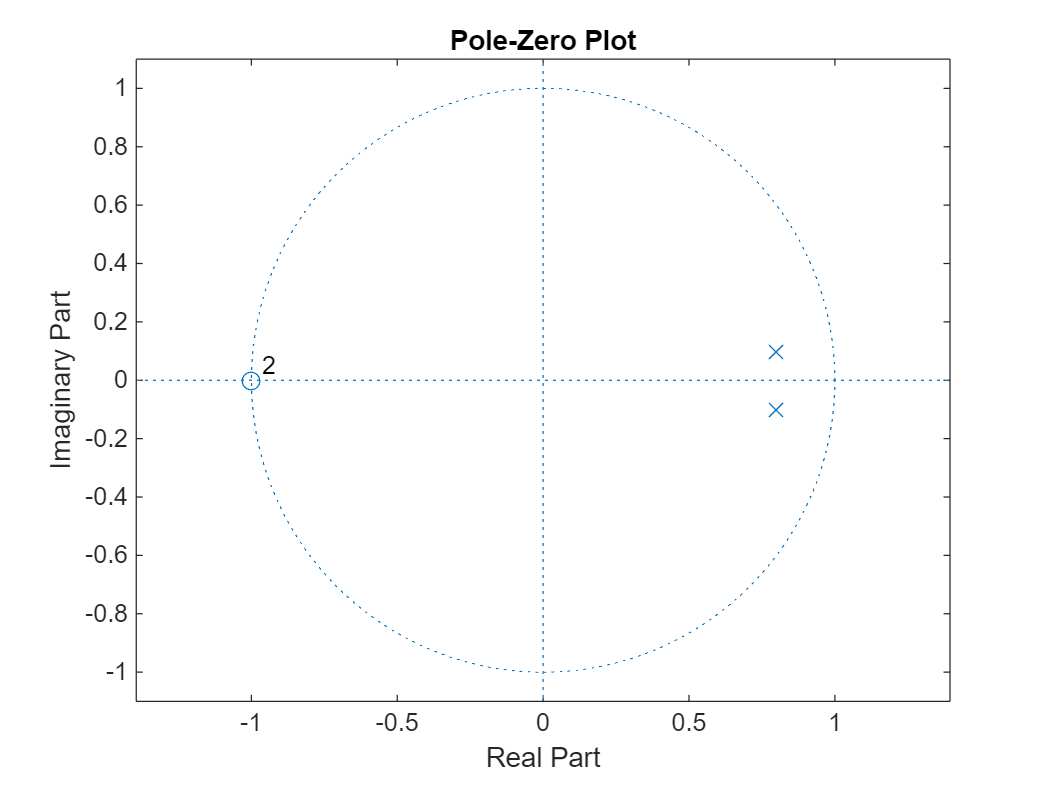


% Plot pole-zero plot
figure;
zplane(num, den);
title('Pole-Zero Plot');

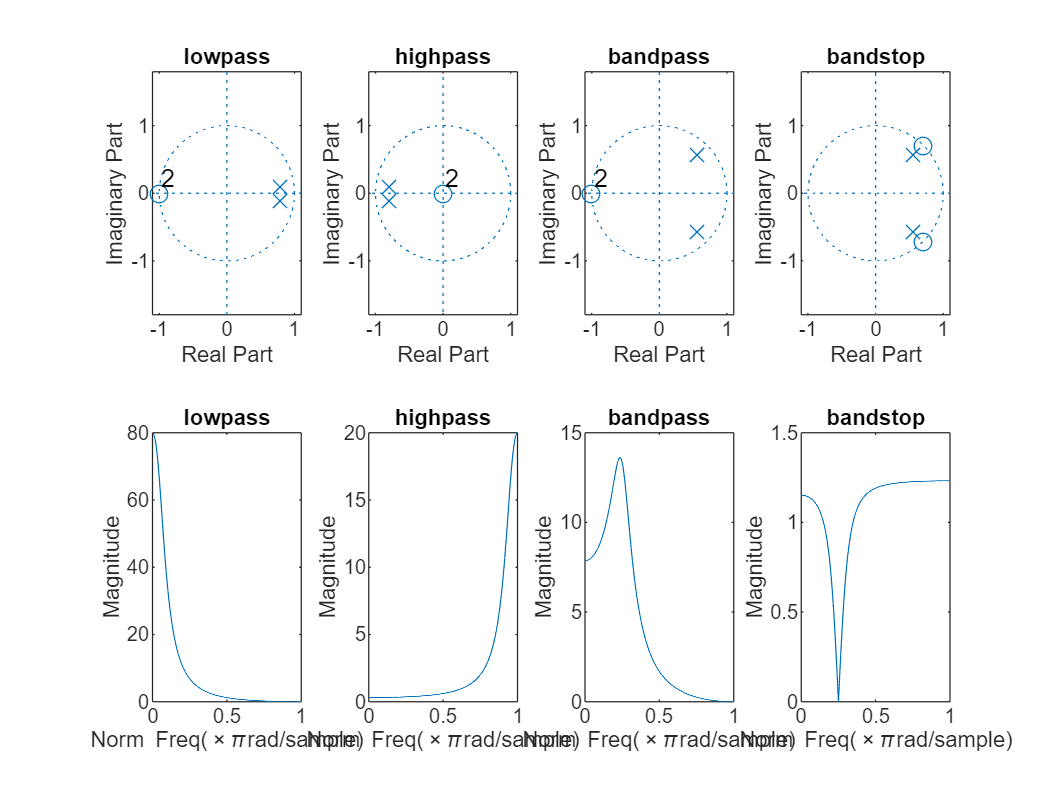

% Define filter types and their poles and zeros
filters = {'lowpass', 'highpass', 'bandpass', 'bandstop'};
poles_zeros = {
    % Lowpass
    [0.8 + 0.1i, 0.8 - 0.1i], [-1, -1];
    % Highpass
    [-0.8 + 0.1i, -0.8 - 0.1i], [0, 0];
    % Bandpass
    [0.8*exp(1i*pi/4), 0.8*exp(-1i*pi/4)], [0, 0, -1, -1];
    % Bandstop
    [0.8*exp(1i*pi/4), 0.8*exp(-1i*pi/4)], [exp(1i*pi/4), exp(-1i*pi/4)]
};

figure;

for i = 1:4
    % Extract poles and zeros
    poles = poles_zeros{i, 1};
    zeros = poles_zeros{i, 2};
    
    % Create transfer function
    [num, den] = zp2tf(zeros(:), poles(:), 1);
    
    % Frequency response
    [H, w] = freqz(num, den, 'half', 1024);
    
    % Plot pole-zero plot
    subplot(2, 4, i);
    zplane(num, den);
    title([filters{i}]);
    
    % Plot magnitude response
    subplot(2, 4, i + 4);
    plot(w/pi, abs(H));
    title([filters{i}]);
    xlabel('Norm Freq(\times\pirad/sample)');
    ylabel('Magnitude');
end

# Echo

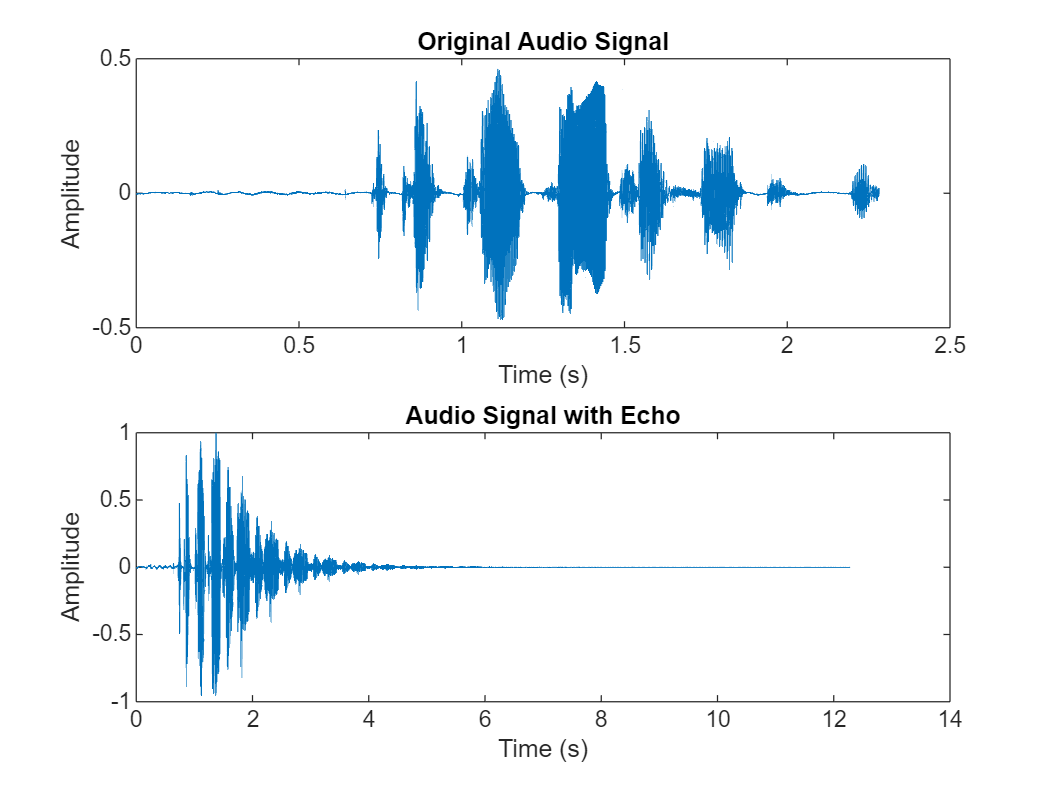

% Load an audio file
clear;
[audioIn, Fs] = audioread('cocktailparty.wav');

audioIn = audioIn(1:100640);


% Parameters for the echo
delayTime = 0.5; % in seconds
feedbackGain = 0.5; % feedback gain

% Calculate the delay in samples
delaySamples = round(delayTime * Fs);

% Determine the length of the output signal
maxEchoLength = length(audioIn) + delaySamples * 20; % Adjust as needed
audioInPadded = [audioIn; zeros(maxEchoLength - length(audioIn), 1)];

% Create the output signal with the same length as the padded input
audioOut = audioInPadded;

% Apply the echo effect
for n = (delaySamples + 1):length(audioInPadded)
    audioOut(n) = audioOut(n) + feedbackGain * audioOut(n - delaySamples);
end

% Normalize the output to prevent clipping
audioOut = audioOut / max(abs(audioOut));

% Write the output to a new audio file
%audiowrite('output_audio_with_echo.wav', audioOut, Fs);

% Play the output signal
sound(audioOut, Fs);

% Plot the original and echoed signals
t = (0:length(audioIn)-1) / Fs;
figure;
subplot(2,1,1);
plot(t, audioIn);
title('Original Audio Signal');
xlabel('Time (s)');
ylabel('Amplitude');

tPadded = (0:length(audioOut)-1) / Fs;
subplot(2,1,2);
plot(tPadded, audioOut);
title('Audio Signal with Echo');
xlabel('Time (s)');
ylabel('Amplitude');


p = [-0.8 + 0.1i; -0.8 - 0.1i]; % Example poles for highpass
z = [0; 0];                     % Example zeros for highpass
k = 1;
[b, a] = zp2tf(z, p, k)
poly(p)
freqz(poly(z), poly(p))

% Define the filter coefficients
b = [0.5, 0.5]; % Numerator coefficients
a = [1, -0.9];  % Denominator coefficients

% Generate a sample input signal (e.g., a sine wave)
fs = 1000; % Sampling frequency
t = 0:1/fs:1; % Time vector
x = sin(2*pi*50*t); % Input signal
t2 = 0:1/fs:2
% Apply the recursive filter
y = filter(b, a, x);

% Plot the input and output signals
figure;
subplot(2,1,1);
plot(t, x);
title('Input Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, y);
title('Filtered Signal');
xlabel('Time (s)');
ylabel('Amplitude');

% Define the filter coefficients
clf;
b = [1, 0]; % Numerator coefficients
a = [1, -0.8]; % Denominator coefficients for echo effect


% Optionally, you can specify the number of points and sampling frequency
n = 50; % Number of points
fs = 1000; % Sampling frequency (Hz)
impz(b, a, n, fs);
[h, t] = impz(b, a, n, fs);


% Define the sampling frequency and delay
clf;
fs = 1000; % Sampling frequency in Hz
delay_ms = 30; % Delay in milliseconds
delay_samples = round(fs * (delay_ms / 1000)); % Convert delay to samples

% Define the filter coefficients for echo effect
b = [1, zeros(1, delay_samples - 1), 0.5]; % Numerator coefficients (original + delayed signal)
a = [1, zeros(1, delay_samples - 1), -0.5]; % Denominator coefficients (feedback term)

% Generate a sample input signal (e.g., a sine wave)
t = 0:1/fs:1; % Time vector
x = sin(2*pi*50*t); % Input signal

% Apply the recursive filter
y = filter(b, a, x);

% Plot the input and output signals
figure;
subplot(2,1,1);
plot(t, x);
title('Input Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, y);
title('Output Signal with Echo Effect');
xlabel('Time (s)');
ylabel('Amplitude');


% Define the sampling frequency and delay
clf;
fs = 1000; % Sampling frequency in Hz
delay_ms = 30; % Delay in milliseconds
delay_samples = round(fs * (delay_ms / 1000)); % Convert delay to samples

% Define the filter coefficients for echo effect
b = [1, zeros(1, delay_samples - 1), 0.85]; % Numerator coefficients (original + delayed signal)
a = [1, zeros(1, delay_samples - 1), -0.5]; % Denominator coefficients (feedback term)
display(zeros(1, delay_samples - 1))

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



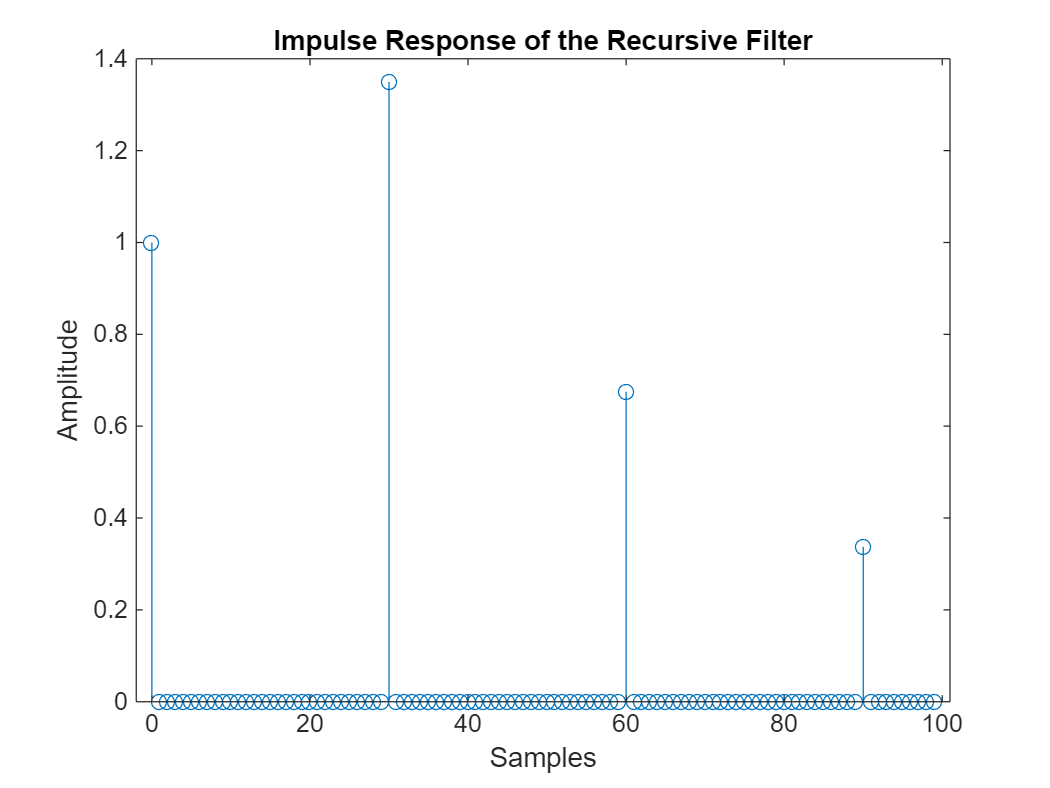

% Compute and plot the impulse response
[h, t] = impz(b, a, 100); % Compute impulse response for 100 points
stem(t, h);
title('Impulse Response of the Recursive Filter');
xlabel('Samples');
ylabel('Amplitude');

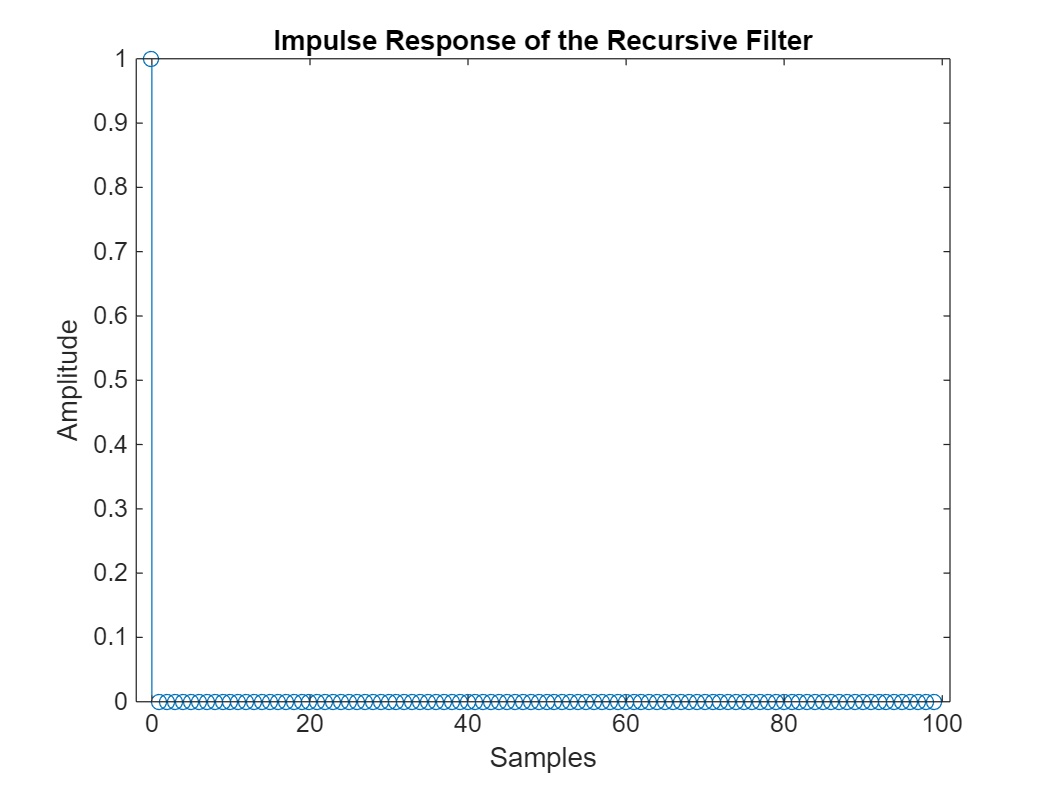

clf;
[lyd, fs] = audioread("cocktailparty.wav");
lydKort = lyd(1:90000);
delay_ms = 300; % Delay in milliseconds
delay_samples = round(fs * (delay_ms / 1000)); % Convert delay to samples

% Define the filter coefficients for echo effect
b = [1, zeros(1, delay_samples - 1), 0.85]; % Numerator coefficients (original + delayed signal)
a = [1, zeros(1, delay_samples - 1), -0.5]; % Denominator coefficients (feedback term)

% Compute and plot the impulse response
[h, t] = impz(b, a, 100); % Compute impulse response for 100 points
stem(t, h);
title('Impulse Response of the Recursive Filter');
xlabel('Samples');
ylabel('Amplitude');




% Apply the filter using the correct coefficients
filteredSignal2 = filter(b, a, lydKort);
sound(filteredSignal2, fs);